Variables simbólicas

L = sym('L')

$$L = L$$

R = sym('R')

$$R = R$$

C = sym('C')

$$C = C$$

rl = sym('r_L')

$$rl = r_{L}$$

rc = sym('r_C')

$$rc = r_{C}$$

D = sym('D')

$$D = \text{D}$$

Vs = sym('Vs')

$$Vs = \mathrm{Vs}$$

u = Vs % matriz de entrada

$$u = \mathrm{Vs}$$


s = sym('s') % variable s

$$s = s$$

Transferencia Vo/Vs

% Llave prendida
A_ON = [-rl/L 0; 0 -1/(C*(R+rc))]

$$A\_ON = \left(\begin{array}{cc} -\frac{r_{L}}{L} & 0\\ 0 & -\frac{1}{C\,\left(R+r_{C}\right)} \end{array}\right)$$

B_ON = [1/L ; 0]

$$B\_ON = \left(\begin{array}{c} \frac{1}{L}\\ 0 \end{array}\right)$$

C_ON = [0 R/(R+rc)]

$$C\_ON = \left(\begin{array}{cc} 0 & \frac{R}{R+r_{C}} \end{array}\right)$$


% Llave apagada
A_OFF = [-(R*rc+R*rl+rc*rl)/(L*(R+rc)), -R/(L*(R+rc)); R/(C*(R+rc)), -1/(C*(R+rc))]

$$A\_OFF = \left(\begin{array}{cc} -\frac{R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}}{L\,\left(R+r_{C}\right)} & -\frac{R}{L\,\left(R+r_{C}\right)}\\ \frac{R}{C\,\left(R+r_{C}\right)} & -\frac{1}{C\,\left(R+r_{C}\right)} \end{array}\right)$$

B_OFF = [sym(0) ; 0]

$$B\_OFF = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

C_OFF = [R*rc/(R+rc), R/(R+rc)]

$$C\_OFF = \left(\begin{array}{cc} \frac{R\,r_{C}}{R+r_{C}} & \frac{R}{R+r_{C}} \end{array}\right)$$


% Promedios
A_p = A_ON*D + A_OFF*(1-D)

$$A\_p = \left(\begin{array}{cc} \frac{\left(\text{D}-1\right)\,\left(R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}\right)}{L\,\left(R+r_{C}\right)}-\frac{\text{D}\,r_{L}}{L} & \frac{R\,\left(\text{D}-1\right)}{L\,\left(R+r_{C}\right)}\\ -\frac{R\,\left(\text{D}-1\right)}{C\,\left(R+r_{C}\right)} & \frac{\text{D}-1}{C\,\left(R+r_{C}\right)}-\frac{\text{D}}{C\,\left(R+r_{C}\right)} \end{array}\right)$$

B_p = B_ON*D + B_OFF*(1-D)

$$B\_p = \left(\begin{array}{c} \frac{\text{D}}{L}\\ 0 \end{array}\right)$$

C_p = C_ON*D + C_OFF*(1-D)

$$C\_p = \left(\begin{array}{cc} -\frac{R\,r_{C}\,\left(\text{D}-1\right)}{R+r_{C}} & \frac{\text{D}\,R}{R+r_{C}}-\frac{R\,\left(\text{D}-1\right)}{R+r_{C}} \end{array}\right)$$


A_p = simplify(A_p)

$$A\_p = \left(\begin{array}{cc} -\frac{R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}-\text{D}\,R\,r_{C}}{L\,\left(R+r_{C}\right)} & \frac{R\,\left(\text{D}-1\right)}{L\,\left(R+r_{C}\right)}\\ -\frac{R\,\left(\text{D}-1\right)}{C\,\left(R+r_{C}\right)} & -\frac{1}{C\,\left(R+r_{C}\right)} \end{array}\right)$$

B_p = simplify(B_p)

$$B\_p = \left(\begin{array}{c} \frac{\text{D}}{L}\\ 0 \end{array}\right)$$

C_p = simplify(C_p)

$$C\_p = \left(\begin{array}{cc} -\frac{R\,r_{C}\,\left(\text{D}-1\right)}{R+r_{C}} & \frac{R}{R+r_{C}} \end{array}\right)$$


% Transferencia Vo/Vs
Hs = (C_p/(s*eye(2)-A_p))*B_p

$$Hs = -\frac{\text{D}\,R\,\left(R+r_{C}\right)\,\left(\text{D}-1\right)\,\left(C\,r_{C}\,s+1\right)}{{\text{D}}^{2}\,R^{2}-C\,\text{D}\,R^{2}\,r_{C}\,s-2\,\text{D}\,R^{2}-C\,\text{D}\,R\,{r_{C}}^{2}\,s-\text{D}\,R\,r_{C}+C\,R^{2}\,r_{C}\,s+C\,L\,R^{2}\,s^{2}+C\,r_{L}\,R^{2}\,s+R^{2}+C\,R\,{r_{C}}^{2}\,s+2\,C\,L\,R\,r_{C}\,s^{2}+2\,C\,r_{L}\,R\,r_{C}\,s+R\,r_{C}+L\,R\,s+r_{L}\,R+C\,L\,{r_{C}}^{2}\,s^{2}+C\,r_{L}\,{r_{C}}^{2}\,s+L\,r_{C}\,s+r_{L}\,r_{C}}$$

H_est = simplify(-(C_p/A_p)*B_p) % Transferencia y/u para estado estacionario (s = 0)

$$H\_est = -\frac{\text{D}\,R\,\left(R+r_{C}\right)\,\left(\text{D}-1\right)}{R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}-2\,\text{D}\,R^{2}+R^{2}+{\text{D}}^{2}\,R^{2}-\text{D}\,R\,r_{C}}$$


% subs(Hs,s,0) % (corroborar)
H_ideal = subs(Hs,[rl,rc],[0,0])

$$H\_ideal = -\frac{\text{D}\,R^{2}\,\left(\text{D}-1\right)}{{\text{D}}^{2}\,R^{2}-2\,\text{D}\,R^{2}+C\,L\,R^{2}\,s^{2}+R^{2}+L\,R\,s}$$

H_est_ideal = subs(Hs,[s,rl,rc],[0,0,0])

$$H\_est\_ideal = -\frac{\text{D}\,R^{2}\,\left(\text{D}-1\right)}{{\text{D}}^{2}\,R^{2}-2\,\text{D}\,R^{2}+R^{2}}$$

Vector de estados en estado estacionario (punto a partir del cual se calcula variaciones de estado y salida en funcion de pequeños cambios de D)

% Estado estacionario: derivada de X respecto de tiempo = 0 (o bien, s=0)
X_est = simplify(-inv(A_p)*B_p*Vs)

$$X\_est = \begin{array}{l} \left(\begin{array}{c} \frac{\text{D}\,\mathrm{Vs}\,\left(R+r_{C}\right)}{\sigma_{1}}\\ -\frac{\text{D}\,R\,\mathrm{Vs}\,\left(R+r_{C}\right)\,\left(\text{D}-1\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}-2\,\text{D}\,R^{2}+R^{2}+{\text{D}}^{2}\,R^{2}-\text{D}\,R\,r_{C} \end{array}$$

X_est_ideal = subs(X_est,[rl,rc],[0,0])

$$X\_est\_ideal = \left(\begin{array}{c} \frac{\text{D}\,R\,\mathrm{Vs}}{{\text{D}}^{2}\,R^{2}-2\,\text{D}\,R^{2}+R^{2}}\\ -\frac{\text{D}\,R^{2}\,\mathrm{Vs}\,\left(\text{D}-1\right)}{{\text{D}}^{2}\,R^{2}-2\,\text{D}\,R^{2}+R^{2}} \end{array}\right)$$

Transferencia ~vo/~d

dD = sym('dD')

$$dD = \mathrm{dD}$$


% Matrices
A_d = simplify(A_p + (A_ON-A_OFF)*dD)

$$A\_d = \left(\begin{array}{cc} -\frac{R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}-\text{D}\,R\,r_{C}-R\,\mathrm{dD}\,r_{C}}{L\,\left(R+r_{C}\right)} & \frac{R\,\left(\text{D}+\mathrm{dD}-1\right)}{L\,\left(R+r_{C}\right)}\\ -\frac{R\,\left(\text{D}+\mathrm{dD}-1\right)}{C\,\left(R+r_{C}\right)} & -\frac{1}{C\,\left(R+r_{C}\right)} \end{array}\right)$$

B_d = simplify(B_p + (B_ON-B_OFF)*dD)

$$B\_d = \left(\begin{array}{c} \frac{\text{D}+\mathrm{dD}}{L}\\ 0 \end{array}\right)$$

C_d = simplify(C_p + (C_ON-C_OFF)*dD)

$$C\_d = \left(\begin{array}{cc} -\frac{R\,r_{C}\,\left(\text{D}+\mathrm{dD}-1\right)}{R+r_{C}} & \frac{R}{R+r_{C}} \end{array}\right)$$


% Despejando ecuacion (29) para derivada de dX = 0 ("X moño puntito = 0")
%dX_est = -inv(A_p)*((A_ON-A_OFF)*X_est + (B_ON-B_OFF)*u)*dD
%dVo_dD_est = -(C_p/A_p)*((A_ON-A_OFF)*X_est + (B_ON-B_OFF)*u) + (C_ON-C_OFF)*X_est
%dVo_dD_est = simplify(dVo_dD_est)

% Para variaciones pequeñas de dD; asumo X_est
dVo_dD = (C_p/(s*eye(2)-A_p))*((A_ON-A_OFF)*X_est+(B_ON-B_OFF)*u) + (C_ON-C_OFF)*X_est

$$dVo\_dD = \begin{array}{l} \frac{L\,R\,\left(R+r_{C}\right)\,\left(\text{D}-1\right)\,\left(C\,r_{C}\,s+1\right)\,\left(\frac{\text{D}\,\mathrm{Vs}\,\left(R+r_{C}\right)\,\left(\frac{r_{L}}{L}-\frac{R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}}{L\,\left(R+r_{C}\right)}\right)}{\sigma_{2}}-\frac{\mathrm{Vs}}{L}+\frac{\text{D}\,R^{2}\,\mathrm{Vs}\,\left(\text{D}-1\right)}{L\,\sigma_{2}}\right)}{\sigma_{1}}-\frac{\text{D}\,R^{2}\,\mathrm{Vs}\,\left(-R\,r_{C}\,{\text{D}}^{2}+R\,r_{C}\,\text{D}+R\,r_{L}+r_{C}\,r_{L}+L\,R\,s+L\,r_{C}\,s\right)}{\sigma_{2}\,\sigma_{1}}-\frac{\text{D}\,R\,\mathrm{Vs}\,r_{C}}{\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}-C\,\text{D}\,R^{2}\,r_{C}\,s-\sigma_{4}-C\,\text{D}\,R\,{r_{C}}^{2}\,s-\text{D}\,R\,r_{C}+C\,R^{2}\,r_{C}\,s+C\,L\,R^{2}\,s^{2}+C\,r_{L}\,R^{2}\,s+R^{2}+C\,R\,{r_{C}}^{2}\,s+2\,C\,L\,R\,r_{C}\,s^{2}+2\,C\,r_{L}\,R\,r_{C}\,s+R\,r_{C}+L\,R\,s+r_{L}\,R+C\,L\,{r_{C}}^{2}\,s^{2}+C\,r_{L}\,{r_{C}}^{2}\,s+L\,r_{C}\,s+r_{L}\,r_{C}\\ \sigma_{2}=R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}-\sigma_{4}+R^{2}+\sigma_{3}-\text{D}\,R\,r_{C}\\ \sigma_{3}={\text{D}}^{2}\,R^{2}\\ \sigma_{4}=2\,\text{D}\,R^{2} \end{array}$$

dVo_dD = simplify(dVo_dD)

$$dVo\_dD = \begin{array}{l} \frac{R\,\mathrm{Vs}\,{\left(R+r_{C}\right)}^{2}\,\left(C\,r_{C}\,s+1\right)\,\left(R+r_{L}-2\,\text{D}\,r_{L}+{\text{D}}^{2}\,R-2\,\text{D}\,R-\text{D}\,L\,s\right)}{\left(R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}-\sigma_{2}+R^{2}+\sigma_{1}-\text{D}\,R\,r_{C}\right)\,\left(\sigma_{1}-C\,\text{D}\,R^{2}\,r_{C}\,s-\sigma_{2}-C\,\text{D}\,R\,{r_{C}}^{2}\,s-\text{D}\,R\,r_{C}+C\,R^{2}\,r_{C}\,s+C\,L\,R^{2}\,s^{2}+C\,r_{L}\,R^{2}\,s+R^{2}+C\,R\,{r_{C}}^{2}\,s+2\,C\,L\,R\,r_{C}\,s^{2}+2\,C\,r_{L}\,R\,r_{C}\,s+R\,r_{C}+L\,R\,s+r_{L}\,R+C\,L\,{r_{C}}^{2}\,s^{2}+C\,r_{L}\,{r_{C}}^{2}\,s+L\,r_{C}\,s+r_{L}\,r_{C}\right)}\\ \mathrm{where}\\ \sigma_{1}={\text{D}}^{2}\,R^{2}\\ \sigma_{2}=2\,\text{D}\,R^{2} \end{array}$$

dVo_dD_ideal = simplify(subs(dVo_dD,[rl,rc],[0,0]))%,[Vs,L,C,R,D],[Vs_,L_,C_,R_,D_])

$$dVo\_dD\_ideal = \frac{\mathrm{Vs}\,\left(R+{\text{D}}^{2}\,R-2\,\text{D}\,R-\text{D}\,L\,s\right)}{{\left(\text{D}-1\right)}^{2}\,\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+C\,L\,R\,s^{2}+L\,s+R\right)}$$

% subs(dVo_dD,s,0) % (corroborar)

Polos y ceros

% PASOS:
% 1) Calcular simbolicamente dVo_dD
% 2) Extraer simbolicamente numerador y denominador
% 3) Extraer simbolicamente coeficientes de numerador y denominador
% 4) Reemplazar símbolos por valores numéricos
% 5) Realizar transferencia

[num,den] = numden(dVo_dD)

$$num = R\,\mathrm{Vs}\,{\left(R+r_{C}\right)}^{2}\,\left(C\,r_{C}\,s+1\right)\,\left(R+r_{L}-2\,\text{D}\,r_{L}+{\text{D}}^{2}\,R-2\,\text{D}\,R-\text{D}\,L\,s\right)$$

$$den = \begin{array}{l} \left(R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}-\sigma_{2}+R^{2}+\sigma_{1}-\text{D}\,R\,r_{C}\right)\,\left(\sigma_{1}-C\,\text{D}\,R^{2}\,r_{C}\,s-\sigma_{2}-C\,\text{D}\,R\,{r_{C}}^{2}\,s-\text{D}\,R\,r_{C}+C\,R^{2}\,r_{C}\,s+C\,L\,R^{2}\,s^{2}+C\,r_{L}\,R^{2}\,s+R^{2}+C\,R\,{r_{C}}^{2}\,s+2\,C\,L\,R\,r_{C}\,s^{2}+2\,C\,r_{L}\,R\,r_{C}\,s+R\,r_{C}+L\,R\,s+r_{L}\,R+C\,L\,{r_{C}}^{2}\,s^{2}+C\,r_{L}\,{r_{C}}^{2}\,s+L\,r_{C}\,s+r_{L}\,r_{C}\right)\\ \mathrm{where}\\ \sigma_{1}={\text{D}}^{2}\,R^{2}\\ \sigma_{2}=2\,\text{D}\,R^{2} \end{array}$$

num_coeffs = coeffs(num,s)%coeffs(subs(num,[rl,rc],[0,0]),s)

$$num\_coeffs = \begin{array}{l} \left(\begin{array}{ccc} R\,\mathrm{Vs}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{1} & C\,R\,\mathrm{Vs}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{1}-\text{D}\,L\,R\,\mathrm{Vs}\,{\left(R+r_{C}\right)}^{2} & -C\,\text{D}\,L\,R\,\mathrm{Vs}\,r_{C}\,{\left(R+r_{C}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R+r_{L}-2\,\text{D}\,r_{L}+{\text{D}}^{2}\,R-2\,\text{D}\,R \end{array}$$

den_coeffs = coeffs(den,s)%coeffs(subs(den,[rl,rc],[0,0]),s)

$$den\_coeffs = \begin{array}{l} \left(\begin{array}{ccc} {\sigma_{1}}^{2} & \sigma_{1}\,\left(L\,r_{C}+L\,R+C\,R\,{r_{C}}^{2}+C\,R^{2}\,r_{C}+C\,R^{2}\,r_{L}+C\,{r_{C}}^{2}\,r_{L}-C\,\text{D}\,R\,{r_{C}}^{2}-C\,\text{D}\,R^{2}\,r_{C}+2\,C\,R\,r_{C}\,r_{L}\right) & \left(C\,L\,R^{2}+2\,C\,L\,R\,r_{C}+C\,L\,{r_{C}}^{2}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,r_{C}+R\,r_{L}+r_{C}\,r_{L}-2\,\text{D}\,R^{2}+R^{2}+{\text{D}}^{2}\,R^{2}-\text{D}\,R\,r_{C} \end{array}$$


%num_a = num_coeffs(1)
%num_b = num_coeffs(2)
%num_c = num_coeffs(3)

%den_a = den_coeffs(1)
%den_b = den_coeffs(2)
%den_c = den_coeffs(3)

%zero1 = simplify((-num_b + sqrt(num_b*num_b - 4*num_a*num_c))/(2*num_a))
%zero2 = simplify((-num_b - sqrt(num_b*num_b - 4*num_a*num_c))/(2*num_a))

%pole1 = simplify((-den_b + sqrt(den_b*den_b - 4*den_a*den_c))/(2*den_a))
%pole2 = simplify((-den_b - sqrt(den_b*den_b - 4*den_a*den_c))/(2*den_a))

Reemplazando símbolos por valores numericos

R_ = 100

R_ = 100

L_ = 10e-3

L_ = 0.0100

C_ = 4.7e-6

C_ = 4.7000e-06

rl_ = 0

rl_ = 0

rc_ = 0

rc_ = 0

D_ = 0.5

D_ = 0.5000

Vs_ = 300

Vs_ = 300


%zeros = vpa(subs([zero1,zero2],[R,L,C,rl,rc,D,Vs],[R_,L_,C_,rl_,rc_,D_,Vs_]))
%poles = vpa(subs([pole1,pole2],[R,L,C,rl,rc,D,Vs],[R_,L_,C_,rl_,rc_,D_,Vs_]))

my_syms = [R,L,C,rl,rc,D,Vs]
my_vals = [R_,L_,C_,rl_,rc_,D_,Vs_]

num_coeffs_ = double(subs(num_coeffs,[R,L,C,rl,rc,D,Vs],[R_,L_,C_,rl_,rc_,D_,Vs_]))

num_coeffs_ = 	1.0e+09 *

    7.5000   -0.0015         0


den_coeffs_ = double(subs(den_coeffs,[R,L,C,rl,rc,D,Vs],[R_,L_,C_,rl_,rc_,D_,Vs_]))

den_coeffs_ = 	1.0e+06 *

    6.2500    0.0025    0.0000


sys = tf(num_coeffs_,den_coeffs_)

sys =
 
     7.5e09 s^2 - 1.5e06 s
  ----------------------------
  6.25e06 s^2 + 2500 s + 1.175
 
Continuous-time transfer function.



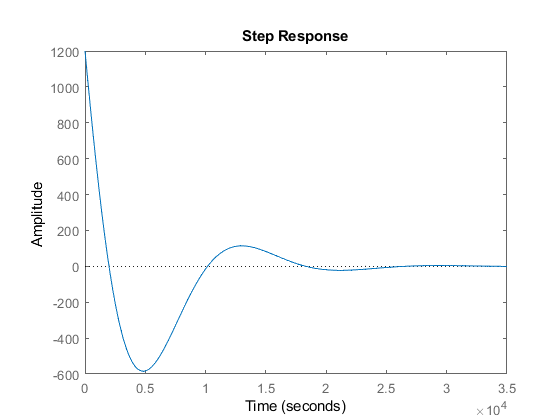

step(sys)

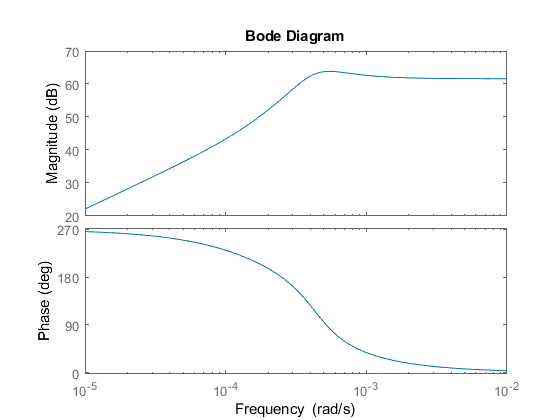

figure('Name','Bode')
bode(sys)

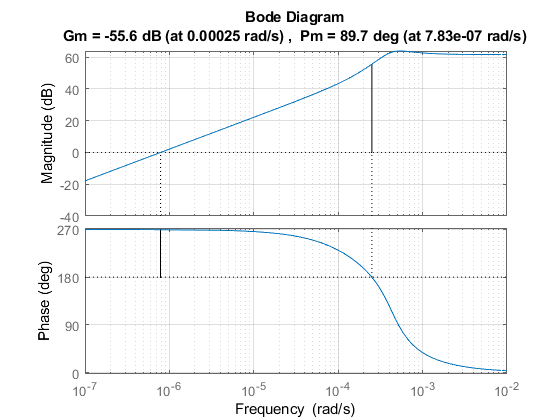

margin(sys)
grid on

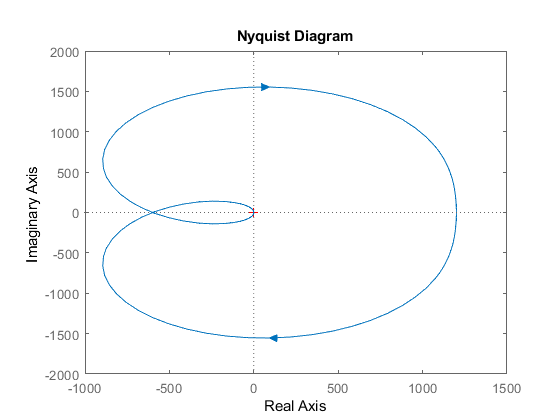

nyquist(sys)